# Example VLM and DLM analysis script

## 1. Initialization

Please setup the APGAA path by running ***init.m*** in the main APGAA directory.

## 2. Run APGAA solver

Run the solver by insert the input filename into the ***run_solver*** command. The tutorials for preparing the input file is included in the **APGAA/examples **folder.

- There are a tutorial and several examples here. Please feel free to select an inputfile by uncomment the selected one and comment the rest. Then, press F5 to run it.

%%%%%%%%%%%%%%%%%%
% tutorial model %
%%%%%%%%%%%%%%%%%%
% (You can open the "inputfile_tutorial.mlx" in editor to see how to write the inputfile.)

rst = run_solver('inputfile_tutorial');

Fx_total = 0.78 N
Fy_total = -0.00 N
Fz_total = 146.40 N
Mx_total = 0.00 N*m
My_total = -26.84 N*m
Mz_total = -0.00 N*m




%%%%%%%%%%%%
% Examples %
%%%%%%%%%%%%

% rst = run_solver('inputfile_EX1_simple_wing'); % Simple wing model
% rst = run_solver('inputfile_EX2_wing_cs'); % Wing with control surfaces
% rst = run_solver('inputfile_EX3_wing_cs_rolling'); % Wing with rotated ailerons
% rst = run_solver('inputfile_EX4_simple_AC'); % Simple aircraft model with wings and tails
% rst = run_solver('inputfile_EX5_full_AC'); % Aircraft model with control surfaces


## 3. Plot the results

Visualize the results by insert the results, ***rst*** variable into the ***plot_panel*** , ***plot_F*** , and ***plot_Cp*** commands.

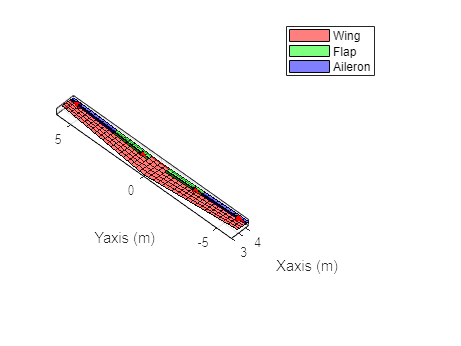

% Plot aerodynamic panels
plot_panel(rst);

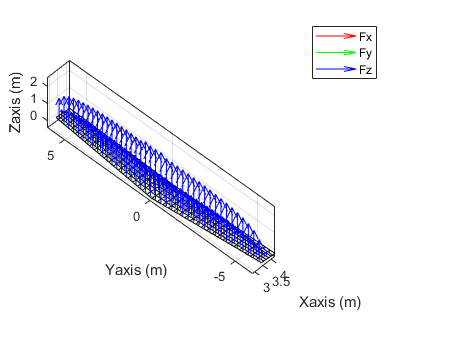


% Plot aerodynamic loadings
plot_F(rst);

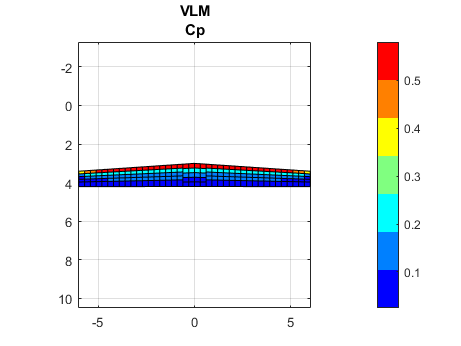

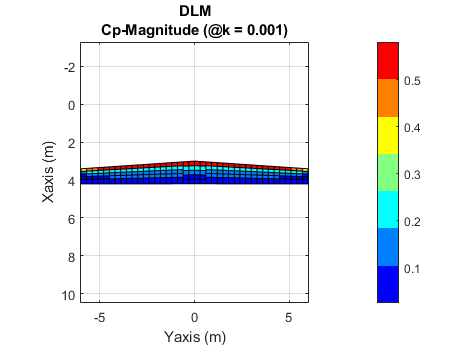

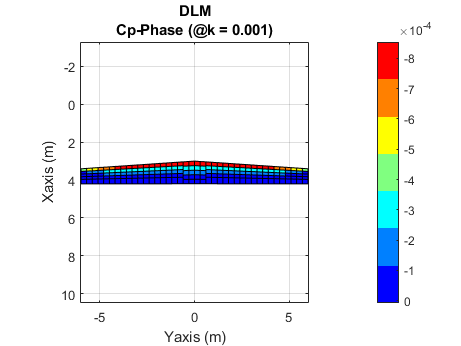

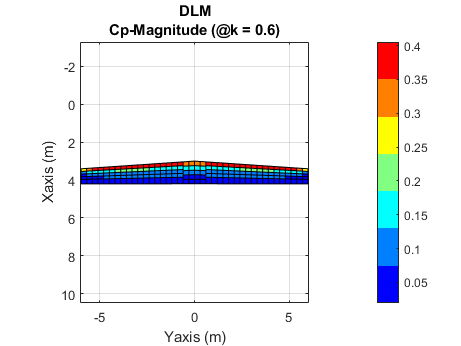

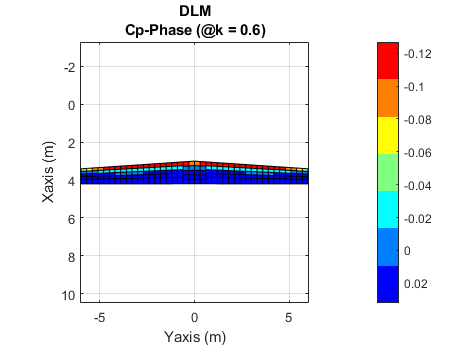

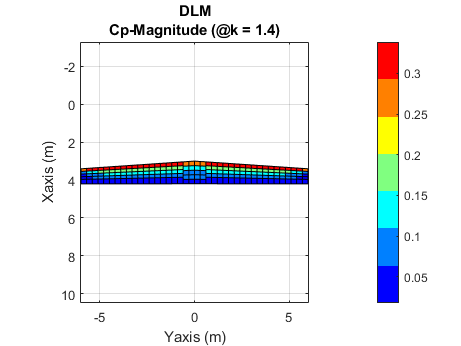

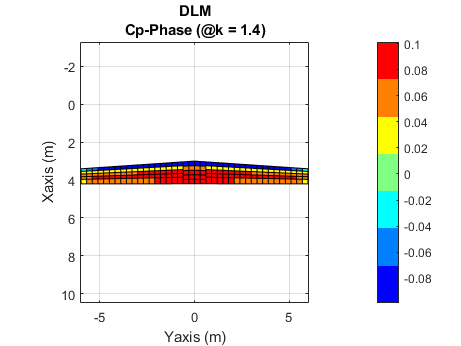


% Plot pressure coefficients (Cp)
plot_Cp(rst);

## Note:

- The init command is required only once after the MATLAB is opened. 

- There are only several commands to setup, run, and visualize the results. They can be executed through the command window too. This script file is not mandatory, only the input file is required.

- The details of all results and data in the ***rst*** variable are thouroughly described in **APGAA/*****vlm_dlm/run_solver.m***